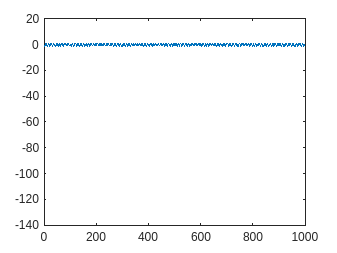

fs = 1*1e9;
fc = 100*1e6;
CR = 20*1e6;
TW = 1*1e-6;
N = TW*fs;
MW = fs/CR;
an = 2*pi*rand(MW,1);
x1 = kron((1:MW)',ones(N/MW,1));
t = (0:1/fs:(N-1)/fs)';
signal = sin(2*pi*fc*t + an(x1));
plot(signal)
Analysis_ES(signal, fs, 128, 'normalized', 1);

cd('A:\data\Cloud\Radar\Reproduction\Distant Sidelobe Suppression for Multi-Timeslot Wide-Gap Frequency-Hopping RFPA Radar');

clc; clear; close all;
% 导入函数定义
addpath(".\function");

% 参数初始化
Parameter = Initialization_Parameter();
save("./data/Parameter.mat","Parameter");

Parameter = Initialization_Parameter();
save("./data/ParameterNon.mat","Parameter");

参数初始化

预先生成相位编码与非相位编码的参数文件,直接选择加载

相位编码信号参数文件：Parameter_PC.mat

非相位编码信号参数文件：Parameter_NonPC.mat

% 非相位编码时
load("./data/Parameter_NonPC.mat");
m = 100;
n = 100;
p = (1:600)';
num_tar = 1;
value = smlk(m, n, p, num_tar, Parameter);
value2 = value.*exp(1j*2*pi*10*1e6*(p-1)*Parameter.TS);
figure
Analysis_ES((value), Parameter.fS, round(Parameter.TW*Parameter.fS),'normalized', 0);hold on;
Analysis_ES((value2), Parameter.fS, round(Parameter.TW*Parameter.fS),'normalized', 0);hold off;
legend(["m=n","m\neqn"]);

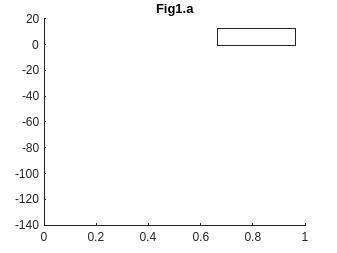

title('Fig1.a');

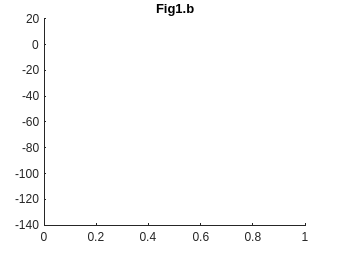

figure
lf_value = conv(Parameter.lf_h,value);
Analysis_ES(lf_value, Parameter.fS, 2*round(Parameter.TW*Parameter.fS),'normalized', 0);hold on;
lf_value2 = conv(Parameter.lf_h,value2);
Analysis_ES(lf_value2, Parameter.fS, 2*round(Parameter.TW*Parameter.fS),'normalized', 0);hold off;
title('Fig1.b');

% 相位编码时
load("./data/Parameter_PC.mat");
m = 98;
n = 100;
p = (1:600)';
num_tar = 1;
value = smlk(m, n, p, num_tar, Parameter);
value2 = zeros(size(p));
for i = 1:Parameter.M
    if i==n
        value = smlk(i, n, p, num_tar, Parameter);
    else
        value2 = value2 + smlk(i, n, p, num_tar, Parameter);
    end
end
% value2 = value.*exp(1j*2*pi*10*1e6*(p-1)*Parameter.TS);

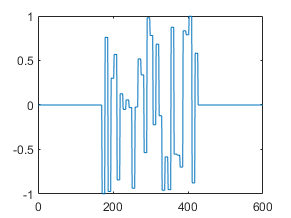

plot(real(value));

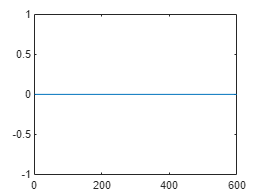

plot(real(value2));

value2 = value.*exp(1j*2*pi*10*10e6*(p-1)*Parameter.TS);

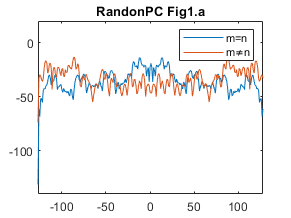

figure
Analysis_ES(real(value), Parameter.fS, round(Parameter.TW*Parameter.fS),'normalized', 0);hold on;
Analysis_ES(real(value2), Parameter.fS, round(Parameter.TW*Parameter.fS),'normalized', 0);hold off;
legend(["m=n","m\neqn"]);
title('RandonPC Fig1.a');

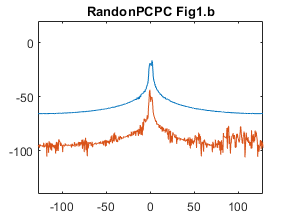

figure
lf_value = conv(Parameter.lf_h,value);
Analysis_ES(lf_value, Parameter.fS, 2*round(Parameter.TW*Parameter.fS),'normalized', 0);hold on;
lf_value2 = conv(Parameter.lf_h,value2);
Analysis_ES(lf_value2, Parameter.fS, 2*round(Parameter.TW*Parameter.fS),'normalized', 0);hold off;
title('RandonPCPC Fig1.b');

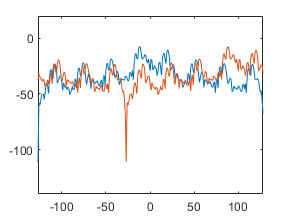

% 编码更新
N1 = min(Parameter.N, Parameter.M-1-n);
N2 = min(Parameter.N, n);
Rm1 = Rm(N1, N2, m, Parameter);
Update_pc(m, Rm1, 1e-6 ,Parameter);
for i = 1:Parameter.M
    if i==n
        value = smlk(i, n, p, num_tar, Parameter);
    else
        value2 = value2 + smlk(i, n, p, num_tar, Parameter);
    end
end
% value = smlk(m, n, p, num_tar, Parameter);
% value2 = value.*exp(1j*2*pi*10*1e6*(p-1)*Parameter.TS);
figure
Analysis_ES(value, Parameter.fS, round(Parameter.TW*Parameter.fS),'normalized', 0);hold on;
Analysis_ES((value2), Parameter.fS, round(Parameter.TW*Parameter.fS),'normalized', 0);hold off;

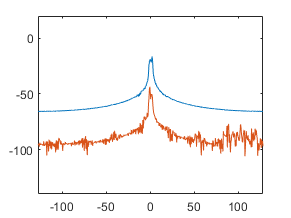

figure
lf_value = conv(Parameter.lf_h,value);
Analysis_ES(lf_value, Parameter.fS, 2*round(Parameter.TW*Parameter.fS),'normalized', 0);hold on;
lf_value2 = conv(Parameter.lf_h,value2);
Analysis_ES(lf_value2, Parameter.fS, 2*round(Parameter.TW*Parameter.fS),'normalized', 0);hold off;

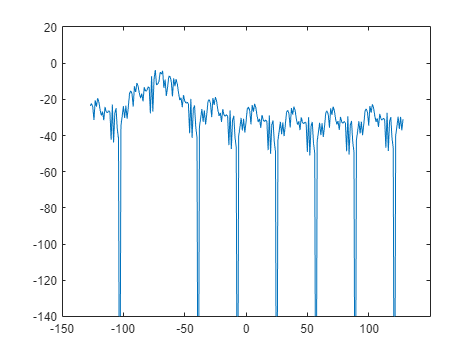

[MPSK, t] = generator_PSK(Parameter.fS,Parameter.fC,Parameter.PhaseCodeParameter.CR,angle(Parameter.PhaseCodeParameter.PhaseCode));
Analysis_ES(MPSK, Parameter.fS);

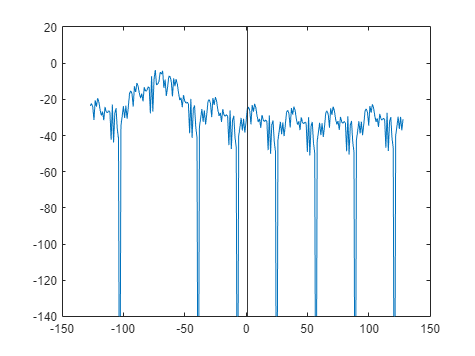

xline(1,'-')

% 移除函数定义
rmpath(".\function");